**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

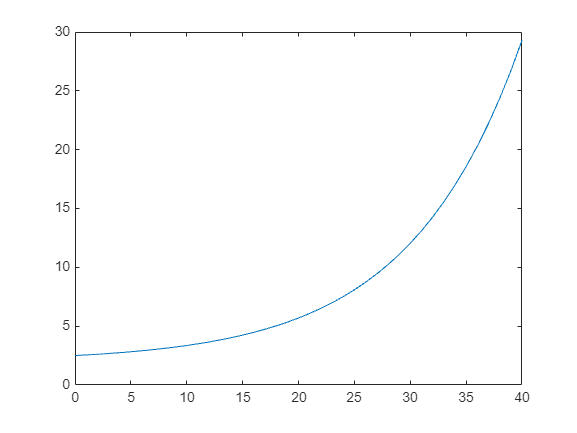

xx = 0 : 1 : 40;
yy = 0.5 * exp(0.1*xx) + 2 ;
plot(xx,yy,'-')

 **2) Now let's assume that we don't know this function, but we know only some points on this function. **

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use linear interpolation to predict the unknown function**

x = linspace(0,40,2) ;
y = 0.5 * exp(0.1*x) + 2 ;
p1 = polyfit(x,y,1);
yy1 = polyval(p1,xx);
plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy1,"-g")
hold on

xtest = 15;
y_pred = polyval(p1,xtest)

y_pred = 12.5497

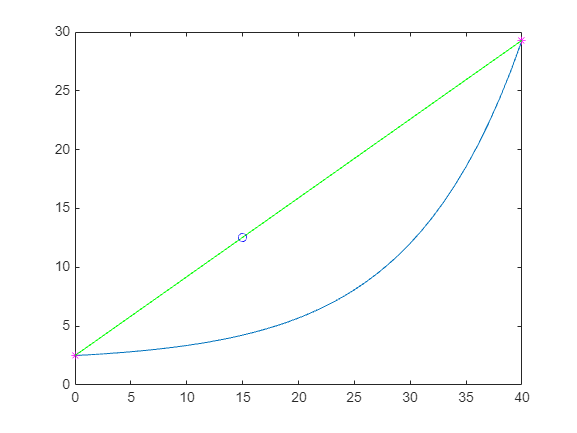

plot(xtest,y_pred,'ob')
hold off

**3) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use quadratic interpolation to predict the unknown function (Quadatic)**

x = linspace(0,40,3) ;
y = 0.5 * exp(0.1*x) + 2 ;
p2 = polyfit(x,y,2);
yy2 = polyval(p2,xx);

plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy2,"-g")
hold on

xtest = 15;
y_pred = polyval(p2,xtest)

y_pred = 2.9825

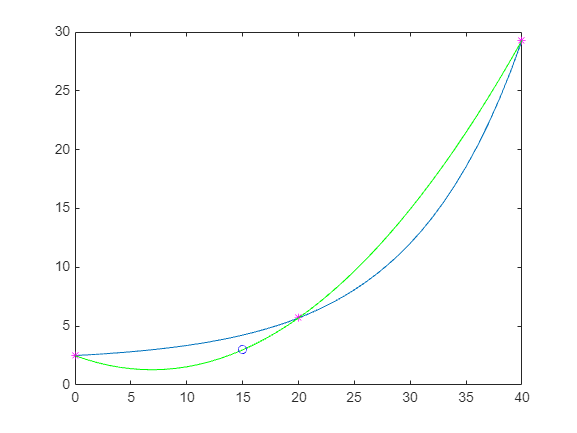

plot(xtest,y_pred,'ob')
hold off

**4) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use cubic interpolation to predict the unknown function**

x = linspace(0,40,4) ;
y = 0.5 * exp(0.1*x) + 2 ;
p3 = polyfit(x,y,3);
yy3 = polyval(p3,xx);

plot(xx,yy,'-')
hold on
plot(x,y,'*m')
hold on
plot(xx,yy3,"-g")
hold on

xtest = 15;
y_pred = polyval(p3,xtest)

y_pred = 4.1222

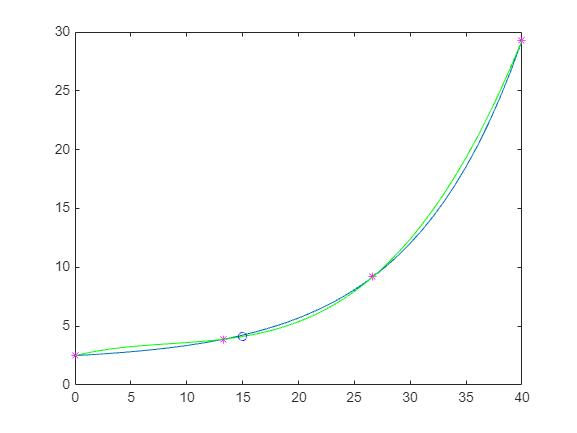

plot(xtest,y_pred,'ob')
hold off